clear;clc;
%load data set
load("SP1bs_F_lower.mat");
load("SP1bs_F_mean.mat");
load("SP1bs_F_upper.mat");
load("SP1bs_M_lower.mat");
load("SP1bs_M_mean.mat");
load("SP1bs_M_upper.mat");
theta_F = struct2array(F_mean);
theta_F_lower = struct2array(F_lower);
theta_F_upper = struct2array(F_upper);
theta_M = struct2array(M_mean);
theta_M_lower = struct2array(M_lower);
theta_M_upper = struct2array(M_upper);
%initial distribution: transition probabilities to these 6 states from the first reproduction of an individual obtained from capture-mark-recapture records.
             %SB           NW           ND           NB           W       D
init_f = [0.698581560; 0.008865248; 0.033687943; 0.095744681; 0.074468085; 0.062056738 ];
init_m = [0.67219153; 0.02394107;0.04419890;0.10313076;0.09576427;0.04051565];

%% female
           [U,I,P,N,R1,R2,R3,R4] = popmat(theta_F);
                n_hat = (inv(I-U))*init_f/sum( (inv(I-U))*init_f);  %stationary relative abundance
              outbern = rewards_eq2019(P,R1,R2,R3,R4);
           LRS_f_mean = outbern.rho1;
           LEX_f_mean = sum(N)';
                      %-------------------------------------------------------
[U,I,P,N,R1,R2,R3,R4] = popmat(theta_F_upper);
                n_hat = (inv(I-U))*init_f/sum( (inv(I-U))*init_f);  %stationary relative abundance
              outbern = rewards_eq2019(P,R1,R2,R3,R4);
           LRS_f_upper = outbern.rho1;
           LEX_f_upper = sum(N)';
            %-------------------------------------------------------
[U,I,P,N,R1,R2,R3,R4] = popmat(theta_F_lower);
                n_hat = (inv(I-U))*init_f/sum( (inv(I-U))*init_f);  %stationary relative abundance
              outbern = rewards_eq2019(P,R1,R2,R3,R4);
           LRS_f_lower = outbern.rho1;
           LEX_f_lower = sum(N)';
%% male
           [U,I,P,N,R1,R2,R3,R4] = popmat(theta_M);
                n_hat = (inv(I-U))*init_m/sum( (inv(I-U))*init_m);  %stationary relative abundance
              outbern = rewards_eq2019(P,R1,R2,R3,R4);
           LRS_m_mean = outbern.rho1;
           LEX_m_mean = sum(N)';
                      %-------------------------------------------------------
[U,I,P,N,R1,R2,R3,R4] = popmat(theta_M_upper);
                n_hat = (inv(I-U))*init_m/sum( (inv(I-U))*init_m);  %stationary relative abundance
              outbern = rewards_eq2019(P,R1,R2,R3,R4);
           LRS_m_upper = outbern.rho1;
           LEX_m_upper = sum(N)';
            %-------------------------------------------------------
[U,I,P,N,R1,R2,R3,R4] = popmat(theta_F_lower);
                n_hat = (inv(I-U))*init_m/sum( (inv(I-U))*init_m);  %stationary relative abundance
              outbern = rewards_eq2019(P,R1,R2,R3,R4);
           LRS_m_lower = outbern.rho1;
           LEX_m_lower = sum(N)';

      %figure
      %bar([LRS_m_mean LRS_f_mean]);hold on
      %errorbar([(0.85:5.85)' (1.15:6.15)'],[LRS_m_mean LRS_f_mean],[LRS_m_lower LRS_f_lower],[LRS_m_upper LRS_f_upper],".","Color",'k')


clc;clear;
load("posterior_M.mat");
load("posterior_F.mat");
M_posterior=struct2table(M_posterior);
F_posterior=struct2table(F_posterior);  
 theta_M = M_posterior(randsample(6000,1000),:); 
 theta_F = F_posterior(randsample(6000,1000),:); 
 theta_F = table2array(theta_F);
  theta_M = table2array(theta_M);
 theta_M (:,7:10) =  theta_M (:,7:10)+0.3;
 theta_F (:,7:10) = theta_F (:,7:10)+0.3;
 init_f = [0.063752277; 0.098360656; 0.034608379; 0.009107468; 0.717668488; 0.076502732 ];
init_m = [0.04135338; 0.10526316; 0.04511278; 0.02443609; 0.68609023; 0.09774436];


LRS_f=[];
LEX_f=[];
mated_f_tb = [];
unmated_f_tb = [];
LRS_f_S = [];
LRS_f_NDNW = [];
LRS_f_DW = [];
LRS_f_mated = [];
LRS_f_unmated = [];
LEX_f_mated = [];
LEX_f_unmated =[];
nbtime_f_mated = [];
nbtime_f_unmated =[];
nbtime_f_mean=[];
NBtime_f_mated = [];
NBtime_f_unmated =[];
NBtime_f_mean=[];
WDtime_f_mated = [];
WDtime_f_unmated =[];
WDtime_f_mean=[];

for i=1:1000
 [U,I,P,N,R1,R2,R3,R4] = popmat(theta_F(i,:));
                n_hat = (inv(I-U))*init_f/sum( (inv(I-U))*init_f);  %stationary relative abundance
              outbern = rewards_eq2019(P,R1,R2,R3,R4);
                LRS_f = [LRS_f outbern.rho1];
              LRS_f_S = [LRS_f_S outbern.rho1(1)];
           LRS_f_NDNW = [LRS_f_NDNW outbern.rho1(2:3)'*(n_hat(2:3)/sum(n_hat(2:3)))];
             LRS_f_DW = [LRS_f_DW outbern.rho1(5:6)'*(n_hat(5:6)/sum(n_hat(5:6)))];
          LRS_f_mated = [LRS_f_mated outbern.rho1(1:4)'*(n_hat(1:4)/sum(n_hat(1:4)))];
        LRS_f_unmated = [LRS_f_unmated outbern.rho1(5:6)'*(n_hat(5:6)/sum(n_hat(5:6)))];
                LEX_f = [LEX_f sum(N)'];
                 temp = sum(N);
          LEX_f_mated = [LEX_f_mated temp(1:3)*(n_hat(1:3)/sum(n_hat(1:3)))];
        LEX_f_unmated = [LEX_f_unmated temp(5:6)*(n_hat(5:6)/sum(n_hat(5:6)))];
                 temp = sum(N(4:6,:));
       nbtime_f_mated = [nbtime_f_mated temp(1:3)*(n_hat(1:3)/sum(n_hat(1:3)))];
     nbtime_f_unmated = [nbtime_f_unmated temp(5:6)*(n_hat(5:6)/sum(n_hat(5:6)))];
        nbtime_f_mean = [nbtime_f_mean  sum(N(4:6,:))'];
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
         temp = N(4,:);
       NBtime_f_mated = [NBtime_f_mated temp(1:3)*(n_hat(1:3)/sum(n_hat(1:3)))];
     NBtime_f_unmated = [NBtime_f_unmated temp(5:6)*(n_hat(5:6)/sum(n_hat(5:6)))];
        NBtime_f_mean = [NBtime_f_mean  sum(N(4:6,:))'];
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        temp = sum(N(5:6,:));
       WDtime_f_mated = [WDtime_f_mated temp(1:3)*(n_hat(1:3)/sum(n_hat(1:3)))];
     WDtime_f_unmated = [WDtime_f_unmated temp(5:6)*(n_hat(5:6)/sum(n_hat(5:6)))];
        WDtime_f_mean = [WDtime_f_mean  sum(N(4:6,:))'];
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
           B = [1, 2, 3];
           outf = abs_MC(U, B);
           outf.lambda=outf.lambda.*[n_hat(1:3)/sum(n_hat(1:3));1;1];
           mated_f_tb=[mated_f_tb outf.lambda(1)+outf.lambda(2)+outf.lambda(3)];
           unmated_f_tb=[unmated_f_tb outf.t_B(2:3)*(n_hat(5:6)/sum(n_hat(5:6)))];
end
 LRS_f_grouped = [LRS_f_mated; LRS_f_unmated];
 nbtime_f_mean = nbtime_f_mean./LEX_f;
 nbtime_f_grouped = [nbtime_f_mated./LEX_f_mated; nbtime_f_unmated./LEX_f_unmated];
 NBtime_f_grouped = [NBtime_f_mated./LEX_f_mated; NBtime_f_unmated./LEX_f_unmated];
 WDtime_f_grouped = [WDtime_f_mated./LEX_f_mated; WDtime_f_unmated./LEX_f_unmated];
 tb_f = [mated_f_tb ;  unmated_f_tb];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
LRS_m=[];
LEX_m=[];
mated_m_tb = [];
unmated_m_tb = [];
LRS_m_S = [];
LRS_m_NDNW = [];
LRS_m_DW = [];
LRS_m_mated = [];
LRS_m_unmated = [];
LEX_m_mated = [];
LEX_m_unmated =[];
nbtime_m_mated = [];
nbtime_m_unmated =[];
nbtime_m_mean=[];
NBtime_m_mated = [];
NBtime_m_unmated =[];
NBtime_m_mean=[];
WDtime_m_mated = [];
WDtime_m_unmated =[];
WDtime_m_mean=[];

 for i=1:1000
[U,I,P,N,R1,R2,R3,R4] = popmat(theta_M(i,:));
                n_hat = (inv(I-U))*init_m/sum( (inv(I-U))*init_m);  %stationary relative abundance
              outbern = rewards_eq2019(P,R1,R2,R3,R4);
                LRS_m = [LRS_m outbern.rho1];
              LRS_m_S = [LRS_m_S outbern.rho1(1)];
           LRS_m_NDNW = [LRS_m_NDNW outbern.rho1(2:3)'*(n_hat(2:3)/sum(n_hat(2:3)))];
             LRS_m_DW = [LRS_m_DW outbern.rho1(5:6)'*(n_hat(5:6)/sum(n_hat(5:6)))];
          LRS_m_mated = [LRS_m_mated outbern.rho1(1:4)'*(n_hat(1:4)/sum(n_hat(1:4)))];
        LRS_m_unmated = [LRS_m_unmated outbern.rho1(5:6)'*(n_hat(5:6)/sum(n_hat(5:6)))];
                LEX_m = [LEX_m sum(N)'];
        nbtime_m_mean = [nbtime_m_mean  sum(N(4:6,:))'];
         temp = sum(N);
          LEX_m_mated = [LEX_m_mated temp(1:3)*(n_hat(1:3)/sum(n_hat(1:3)))];
        LEX_m_unmated = [LEX_m_unmated temp(5:6)*(n_hat(5:6)/sum(n_hat(5:6)))];
                 temp = sum(N(4:6,:));
       nbtime_m_mated = [nbtime_m_mated temp(1:3)*(n_hat(1:3)/sum(n_hat(1:3)))];
     nbtime_m_unmated = [nbtime_m_unmated temp(5:6)*(n_hat(5:6)/sum(n_hat(5:6)))];
     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
          temp = N(4,:);
       NBtime_m_mated = [NBtime_m_mated temp(1:3)*(n_hat(1:3)/sum(n_hat(1:3)))];
     NBtime_m_unmated = [NBtime_m_unmated temp(5:6)*(n_hat(5:6)/sum(n_hat(5:6)))];
        NBtime_m_mean = [NBtime_m_mean  sum(N(4:6,:))'];
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        temp = sum(N(5:6,:));
       WDtime_m_mated = [WDtime_m_mated temp(1:3)*(n_hat(1:3)/sum(n_hat(1:3)))];
     WDtime_m_unmated = [WDtime_m_unmated temp(5:6)*(n_hat(5:6)/sum(n_hat(5:6)))];
        WDtime_m_mean = [WDtime_m_mean  sum(N(4:6,:))'];
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
           B = [1, 2, 3];
           outm = abs_MC(U, B);
           outm.lambda=outm.lambda.*[n_hat(1:3)/sum(n_hat(1:3));1;1];
           mated_m_tb=[mated_m_tb outm.lambda(1)+outm.lambda(2)+outm.lambda(3)];
           unmated_m_tb=[unmated_m_tb outm.t_B(2:3)*(n_hat(5:6)/sum(n_hat(5:6)))];
 end
 LRS_m_grouped = [LRS_m_mated; LRS_m_unmated];
  nbtime_m_mean = nbtime_m_mean./LEX_m;
   nbtime_m_grouped = [nbtime_m_mated./LEX_m_mated; nbtime_m_unmated./LEX_m_unmated];
   NBtime_m_grouped = [NBtime_m_mated./LEX_m_mated; NBtime_m_unmated./LEX_m_unmated];
 WDtime_m_grouped = [WDtime_m_mated./LEX_m_mated; WDtime_m_unmated./LEX_m_unmated];
 tb_m = [mated_m_tb ;  unmated_m_tb];

SEM = std(LRS_m,0,2)/sqrt(length(LRS_m));               % Standard Error
ts = tinv([0.025  0.975],length(LRS_m)-1);      % T-Score
CI_m = mean(LRS_m,2) + ts.*SEM;         
SEM = std(LRS_f,0,2)/sqrt(length(LRS_f));               % Standard Error
ts = tinv([0.025  0.975],length(LRS_f)-1);      % T-Score
CI_f = mean(LRS_f,2) + ts.*SEM;      
fig=figure

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [455 334 560 420]
       Units: 'pixels'

  Show all properties


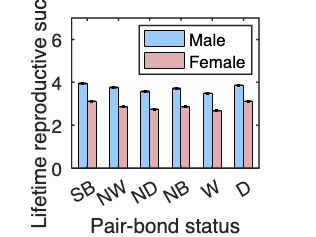

b=bar([mean(LRS_m,2) mean(LRS_f,2)],1);hold on;ylim([0 7]);xlim([0.5 6.5]);
errorbar([(0.85:5.85)' (1.15:6.15)'],[mean(LRS_m,2) mean(LRS_f,2)],[CI_m(:,1)-mean(LRS_m,2) CI_f(:,1)-mean(LRS_f,2)],[CI_m(:,2)-mean(LRS_m,2) CI_f(:,2)-mean(LRS_f,2)],".","Color",'k');
b(2).FaceColor=[225 175 175]/256;
b(1).FaceColor=[153, 204, 255]/256;
pbaspect([2 1.6 1]);
xticklabels({'SB','NW',"ND","NB","W","D"})
xlabel("Pair-bond status")
ylabel("Lifetime reproductive success")
set(gca,'box','on')
legend('Male','Female')
%legendflex(gca, {'Male','Female'}, 'xscale', 0.5)
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica');
exportgraphics(fig,'figure/LRS.pdf','BackgroundColor','none')
exportgraphics(fig,'figure/LRS.png','BackgroundColor','none')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
SEM = std(LRS_m,0,2)/sqrt(length(LRS_m));               % Standard Error
ts = tinv([0.025  0.975],length(LRS_m)-1);      % T-Score
CI_m = mean(LRS_m,2) + ts.*SEM;         
SEM = std(LRS_f,0,2)/sqrt(length(LRS_f));               % Standard Error
ts = tinv([0.025  0.975],length(LRS_f)-1);      % T-Score
CI_f = mean(LRS_f,2) + ts.*SEM;      
fig=figure

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [455 334 560 420]
       Units: 'pixels'

  Show all properties


b=bar([mean(LRS_m,2) mean(LRS_f,2)],1);hold on;ylim([0 7]);xlim([0.5 6.5]);
errorbar([(0.85:5.85)' (1.15:6.15)'],[mean(LRS_m,2) mean(LRS_f,2)],[CI_m(:,1)-mean(LRS_m,2) CI_f(:,1)-mean(LRS_f,2)],[CI_m(:,2)-mean(LRS_m,2) CI_f(:,2)-mean(LRS_f,2)],".","Color",'k');
b(2).FaceColor=[225 175 175]/256

b =   1×2 Bar array:

    Bar    Bar


b(1).FaceColor=[153, 204, 255]/256

b =   1×2 Bar array:

    Bar    Bar


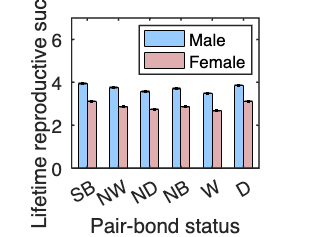

pbaspect([2 1.6 1]);
xticklabels({'SB','NW',"ND","NB","W","D"})
xlabel("Pair-bond status")
ylabel("Lifetime reproductive success")
set(gca,'box','on')
legend('Male','Female')
%legendflex(gca, {'Male','Female'}, 'xscale', 0.5)
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica');
exportgraphics(fig,'figure/LRS.pdf','BackgroundColor','none')
exportgraphics(fig,'figure/LRS.png','BackgroundColor','none')

SEM = std(LEX_m,0,2)/sqrt(length(LEX_m));               % Standard Error
ts = tinv([0.025  0.975],length(LEX_m)-1);      % T-Score
CI_m = mean(LEX_m,2) + ts.*SEM;         
SEM = std(LEX_f,0,2)/sqrt(length(LEX_f));               % Standard Error
ts = tinv([0.025  0.975],length(LEX_f)-1);      % T-Score
CI_f = mean(LEX_f,2) + ts.*SEM;      
fig=figure

fig =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [455 334 560 420]
       Units: 'pixels'

  Show all properties


b=bar([mean(LEX_m,2) mean(LEX_f,2)],1);hold on;ylim([0 20]);xlim([0.5 6.5]);
errorbar([(0.85:5.85)' (1.15:6.15)'],[mean(LEX_m,2) mean(LEX_f,2)],[CI_m(:,1)-mean(LEX_m,2) CI_f(:,1)-mean(LEX_f,2)],[CI_m(:,2)-mean(LEX_m,2) CI_f(:,2)-mean(LEX_f,2)],".","Color",'k');
b(2).FaceColor=[225 175 175]/256

b =   1×2 Bar array:

    Bar    Bar


b(1).FaceColor=[153, 204, 255]/256

b =   1×2 Bar array:

    Bar    Bar


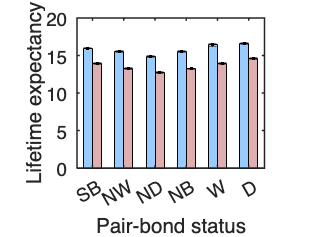

pbaspect([2 1.6 1]);
xticklabels({'SB','NW',"ND","NB","W","D"})
xlabel("Pair-bond status")
ylabel("Lifetime expectancy")
set(gca,'box','on')
%legend('Male','Female')
%legendflex(gca, {'Male','Female'}, 'xscale', 0.5)
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica');
exportgraphics(fig,'figure/LEX.pdf','BackgroundColor','none')
exportgraphics(fig,'figure/LEX.png','BackgroundColor','none')

SEM = std(nbtime_m_mean,0,2)/sqrt(length(nbtime_m_mean));               % Standard Error
ts = tinv([0.025  0.975],length(nbtime_m_mean)-1);      % T-Score
CI_m = mean(nbtime_m_mean,2) + ts.*SEM;         
SEM = std(nbtime_f_mean,0,2)/sqrt(length(nbtime_f_mean));               % Standard Error
ts = tinv([0.025  0.975],length(nbtime_f_mean)-1);      % T-Score
CI_f = mean(nbtime_f_mean,2) + ts.*SEM;      
fig=figure

fig =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [455 334 560 420]
       Units: 'pixels'

  Show all properties


b=bar([mean(nbtime_m_mean,2) mean(nbtime_f_mean,2)],1);hold on;ylim([0 1]);xlim([0.5 6.5]);
errorbar([(0.85:5.85)' (1.15:6.15)'],[mean(nbtime_m_mean,2) mean(nbtime_f_mean,2)],[CI_m(:,1)-mean(nbtime_m_mean,2) CI_f(:,1)-mean(nbtime_f_mean,2)],[CI_m(:,2)-mean(nbtime_m_mean,2) CI_f(:,2)-mean(nbtime_f_mean,2)],".","Color",'k');
b(2).FaceColor=[225 175 175]/256

b =   1×2 Bar array:

    Bar    Bar


b(1).FaceColor=[153, 204, 255]/256

b =   1×2 Bar array:

    Bar    Bar


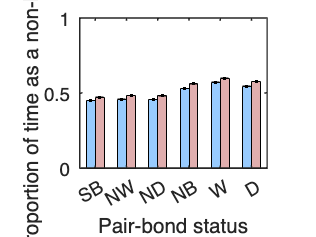

pbaspect([2 1.6 1]);
xticklabels({'SB','NW',"ND","NB","W","D"})
xlabel("Pair-bond status")
ylabel("Proportion of time as a non-breeder")
set(gca,'box','on')
%legend('Male','Female')
%legendflex(gca, {'Male','Female'}, 'xscale', 0.5)
set(gca,'linewidth',1.1,'fontsize',14,'fontname','Helvetica');
exportgraphics(fig,'figure/nbtime.pdf','BackgroundColor','none')
exportgraphics(fig,'figure/nbtime.png','BackgroundColor','none')

SEM = std(tb_m,0,2)/sqrt(length(tb_m));               % Standard Error
ts = tinv([0.025  0.975],length(tb_m)-1);      % T-Score
CI_m = mean(tb_m,2) + ts.*SEM;         
SEM = std(tb_f,0,2)/sqrt(length(tb_f));               % Standard Error
ts = tinv([0.025  0.975],length(tb_f)-1);      % T-Score
CI_f = mean(tb_f,2) + ts.*SEM;      
fig=figure;
fig.Position=[560,240,350,400]

fig =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [560 240 350 400]
       Units: 'pixels'

  Show all properties


b=bar([mean(tb_m,2) mean(tb_f,2)],0.8);hold on;ylim([0 5]);xlim([0.5 2.5]);
errorbar([(0.85:1.85)' (1.15:2.15)'],[mean(tb_m,2) mean(tb_f,2)],[CI_m(:,1)-mean(tb_m,2) CI_f(:,1)-mean(tb_f,2)],[CI_m(:,2)-mean(tb_m,2) CI_f(:,2)-mean(tb_f,2)],".","Color",'k');
b(2).FaceColor=[225 175 175]/256

b =   1×2 Bar array:

    Bar    Bar


b(1).FaceColor=[153, 204, 255]/256

b =   1×2 Bar array:

    Bar    Bar


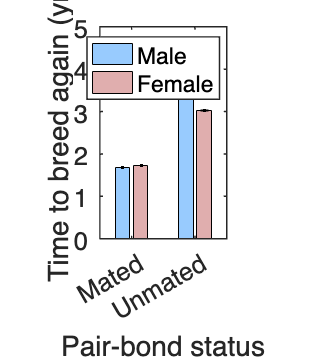

pbaspect([1.2 2 1]);
xticklabels({'Mated','Unmated'})
xlabel("Pair-bond status")
ylabel("Time to breed again (yr)")
set(gca,'box','on')
legend('Male','Female')
%legendflex(gca, {'Male','Female'}, 'xscale', 0.5)
set(gca,'linewidth',1.1,'fontsize',19,'fontname','Helvetica');
exportgraphics(fig,'figure/to_breed.pdf','BackgroundColor','none')
exportgraphics(fig,'figure/to_breed.png','BackgroundColor','none')

SEM = std(nbtime_m_grouped,0,2)/sqrt(length(nbtime_m_grouped));               % Standard Error
ts = tinv([0.025  0.975],length(nbtime_m_grouped)-1);      % T-Score
CI_m = mean(nbtime_m_grouped,2) + ts.*SEM;         
SEM = std(nbtime_f_grouped,0,2)/sqrt(length(nbtime_f_grouped));               % Standard Error
ts = tinv([0.025  0.975],length(nbtime_f_grouped)-1);      % T-Score
CI_f = mean(nbtime_f_grouped,2) + ts.*SEM;      
fig=figure

fig =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [455 334 560 420]
       Units: 'pixels'

  Show all properties


fig.Position=[560,240,350,400];
b=bar([mean(nbtime_m_grouped,2)*100 mean(nbtime_f_grouped,2)*100],0.8);hold on;ylim([0 100]);xlim([0.5 2.5]);
errorbar([(0.85:1.85)' (1.15:2.15)'],[mean(nbtime_m_grouped,2)*100 mean(nbtime_f_grouped,2)*100],[CI_m(:,1)-mean(nbtime_m_grouped,2) CI_f(:,1)-mean(nbtime_f_grouped,2)],[CI_m(:,2)-mean(nbtime_m_grouped,2) CI_f(:,2)-mean(nbtime_f_grouped,2)],".","Color",'k');
b(2).FaceColor=[225 175 175]/256

b =   1×2 Bar array:

    Bar    Bar


b(1).FaceColor=[153, 204, 255]/256

b =   1×2 Bar array:

    Bar    Bar


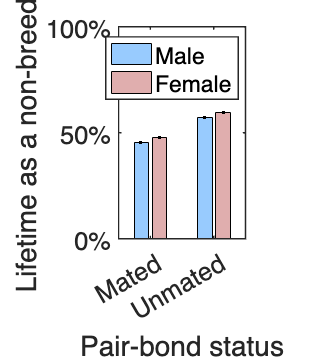

pbaspect([1.2 2 1]);
ytickformat('percentage')
xticklabels({'Mated','Unmated'})
xlabel("Pair-bond status")
ylabel("Lifetime as a non-breeder")
set(gca,'box','on')
legend('Male','Female')
%legendflex(gca, {'Male','Female'}, 'xscale', 0.5)
set(gca,'linewidth',1.1,'fontsize',19,'fontname','Helvetica');
exportgraphics(fig,'figure/nb_proportion_grouped.pdf','BackgroundColor','none')
exportgraphics(fig,'figure/nb_proportion_grouped.png','BackgroundColor','none')

SEM = std(NBtime_m_grouped,0,2)/sqrt(length(NBtime_m_grouped));               % Standard Error
ts = tinv([0.025  0.975],length(NBtime_m_grouped)-1);      % T-Score
CI_m = mean(NBtime_m_grouped,2) + ts.*SEM;         
SEM = std(NBtime_f_grouped,0,2)/sqrt(length(NBtime_f_grouped));               % Standard Error
ts = tinv([0.025  0.975],length(NBtime_f_grouped)-1);      % T-Score
CI_f = mean(NBtime_f_grouped,2) + ts.*SEM;      
fig=figure

fig =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [455 334 560 420]
       Units: 'pixels'

  Show all properties


fig.Position=[560,240,350,400];
b=bar([mean(NBtime_m_grouped,2)*100 mean(NBtime_f_grouped,2)*100],0.8);hold on;ylim([0 100]);xlim([0.5 2.5]);
errorbar([(0.85:1.85)' (1.15:2.15)'],[mean(NBtime_m_grouped,2)*100 mean(NBtime_f_grouped,2)*100],[CI_m(:,1)-mean(NBtime_m_grouped,2) CI_f(:,1)-mean(NBtime_f_grouped,2)],[CI_m(:,2)-mean(NBtime_m_grouped,2) CI_f(:,2)-mean(NBtime_f_grouped,2)],".","Color",'k');
b(2).FaceColor=[225 175 175]/256

b =   1×2 Bar array:

    Bar    Bar


b(1).FaceColor=[153, 204, 255]/256

b =   1×2 Bar array:

    Bar    Bar


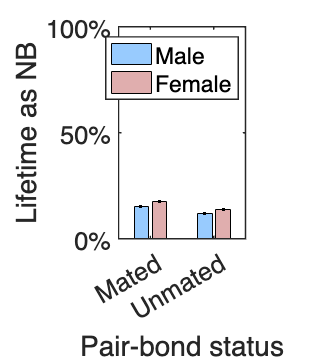

pbaspect([1.2 2 1]);
ytickformat('percentage')
xticklabels({'Mated','Unmated'})
xlabel("Pair-bond status")
ylabel("Lifetime as NB")
set(gca,'box','on')
legend('Male','Female')
%legendflex(gca, {'Male','Female'}, 'xscale', 0.5)
set(gca,'linewidth',1.1,'fontsize',19,'fontname','Helvetica');
exportgraphics(fig,'figure/NBstate_proportion_grouped.pdf','BackgroundColor','none')
exportgraphics(fig,'figure/NBstate_proportion_grouped.png','BackgroundColor','none')

SEM = std(WDtime_m_grouped*100,0,2)/sqrt(length(WDtime_m_grouped));               % Standard Error
ts = tinv([0.025  0.975],length(WDtime_m_grouped)-1);      % T-Score
CI_m = mean(WDtime_m_grouped,2) + ts.*SEM;         
SEM = std(WDtime_f_grouped*100,0,2)/sqrt(length(WDtime_f_grouped));               % Standard Error
ts = tinv([0.025  0.975],length(WDtime_f_grouped)-1);      % T-Score
CI_f = mean(WDtime_f_grouped,2) + ts.*SEM;      
fig=figure

fig =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [455 334 560 420]
       Units: 'pixels'

  Show all properties


fig.Position=[560,240,350,400];
b=bar([mean(WDtime_m_grouped,2)*100 mean(WDtime_f_grouped,2)*100],0.8);hold on;ylim([0 100]);xlim([0.5 2.5]);
errorbar([(0.85:1.85)' (1.15:2.15)'],[mean(WDtime_m_grouped,2)*100 mean(WDtime_f_grouped,2)*100],[CI_m(:,1)-mean(WDtime_m_grouped,2) CI_f(:,1)-mean(WDtime_f_grouped,2)],[CI_m(:,2)-mean(WDtime_m_grouped,2) CI_f(:,2)-mean(WDtime_f_grouped,2)],".","Color",'k');
b(2).FaceColor=[225 175 175]/256

b =   1×2 Bar array:

    Bar    Bar


b(1).FaceColor=[153, 204, 255]/256

b =   1×2 Bar array:

    Bar    Bar


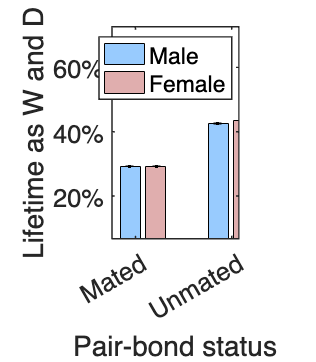

pbaspect([1.2 2 1]);
ytickformat('percentage')
xticklabels({'Mated','Unmated'})
xlabel("Pair-bond status")
ylabel("Lifetime as W and D")
set(gca,'box','on')
legend('Male','Female')
%legendflex(gca, {'Male','Female'}, 'xscale', 0.5)
set(gca,'linewidth',1.1,'fontsize',19,'fontname','Helvetica');
exportgraphics(fig,'figure/WDstate_proportion_grouped.pdf','BackgroundColor','none')
exportgraphics(fig,'figure/WDstate_proportion_grouped.png','BackgroundColor','none')

SEM = std(LRS_m_grouped,0,2)/sqrt(length(LRS_m_grouped));               % Standard Error
ts = tinv([0.025  0.975],length(LRS_m_grouped)-1);      % T-Score
CI_m = mean(LRS_m_grouped,2) + ts.*SEM;         
SEM = std(LRS_f_grouped,0,2)/sqrt(length(LRS_f_grouped));               % Standard Error
ts = tinv([0.025  0.975],length(LRS_f_grouped)-1);      % T-Score
CI_f = mean(LRS_f_grouped,2) + ts.*SEM;      
fig=figure;
fig.Position=[560,240,350,400];
b=bar([mean(LRS_m_grouped,2) mean(LRS_f_grouped,2)],0.8);hold on;ylim([0 4.5]);xlim([0.5 2.5]);
errorbar([(0.85:1.85)' (1.15:2.15)'],[mean(LRS_m_grouped,2) mean(LRS_f_grouped,2)],[CI_m(:,1)-mean(LRS_m_grouped,2) CI_f(:,1)-mean(LRS_f_grouped,2)],[CI_m(:,2)-mean(LRS_m_grouped,2) CI_f(:,2)-mean(LRS_f_grouped,2)],".","Color",'k');
b(2).FaceColor=[225 175 175]/256

b =   1×2 Bar array:

    Bar    Bar


b(1).FaceColor=[153, 204, 255]/256

b =   1×2 Bar array:

    Bar    Bar


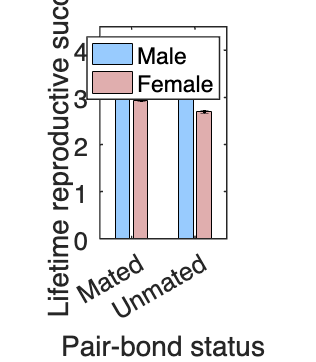

pbaspect([1.2 2 1]);
xticklabels({'Mated','Unmated'})
xlabel("Pair-bond status")
ylabel("Lifetime reproductive success")
set(gca,'box','on')
legend('Male','Female')
%legendflex(gca, {'Male','Female'}, 'xscale', 0.5)
set(gca,'linewidth',1.1,'fontsize',19,'fontname','Helvetica');
exportgraphics(fig,'figure/LRS_grouped.pdf','BackgroundColor','none')
exportgraphics(fig,'figure/LRS_grouped.png','BackgroundColor','none')